Part 4 - Homework

% 1.
fprintf('Exercise 1');

Exercise 1

[I, cmap] = imread("therese.gif");

% 2.
fprintf('Exercise 2');

Exercise 2

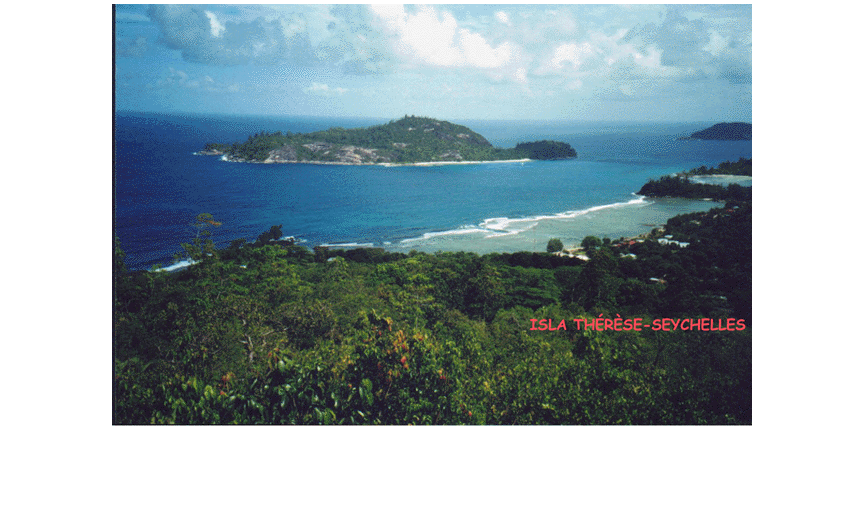

imshow(I, cmap);

% 3.
fprintf('Exercise 3');

Exercise 3

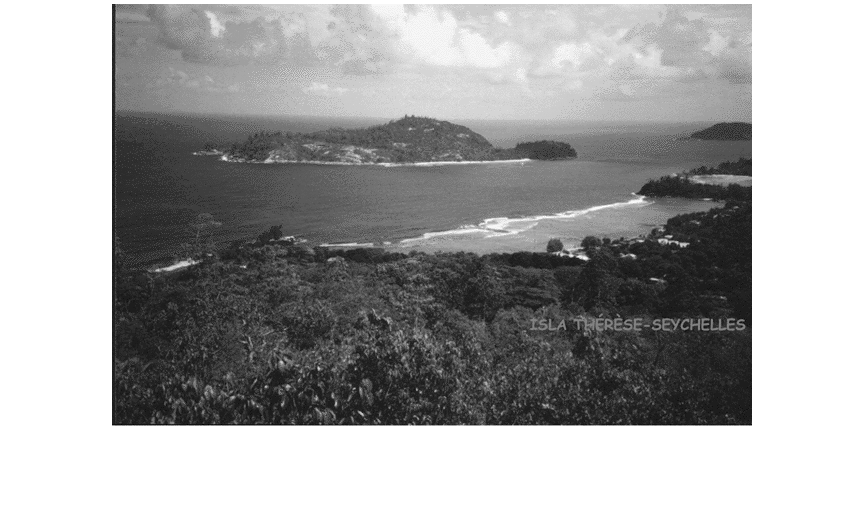

i = ind2gray(I, cmap);
imshow(i);

fprintf('min: %d', min(i,[],'all'));

min: 0

fprintf('max: %d\n', max(i,[],'all'));

max: 255


% 4.
fprintf('Exercise 4');

Exercise 4

% returns a row vector with rows, columns, and number of colorchannels
[rows, columns] = size(i); 
fprintf('Size GreyScale: %dx%d', rows,columns);

Size GreyScale: 422x640

% 5.
fprintf('Exercise 5');

Exercise 5

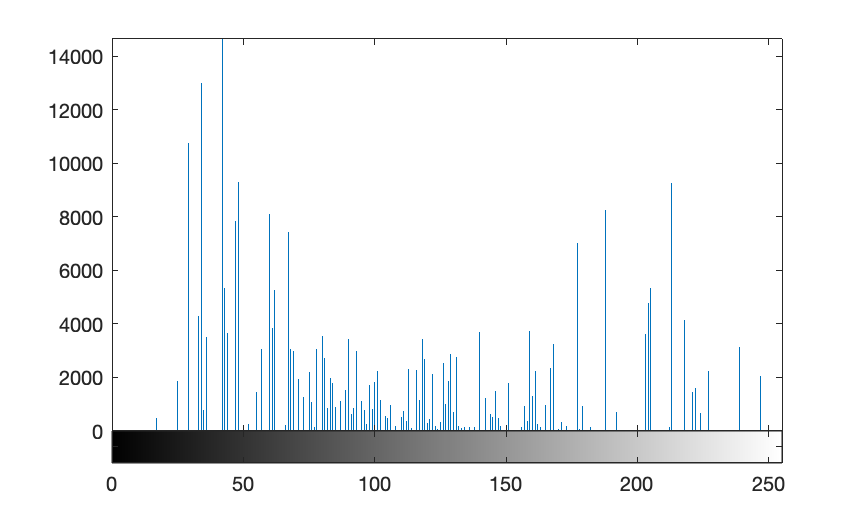

imhist(i);

% 6.
fprintf('Exercise 6');

Exercise 6

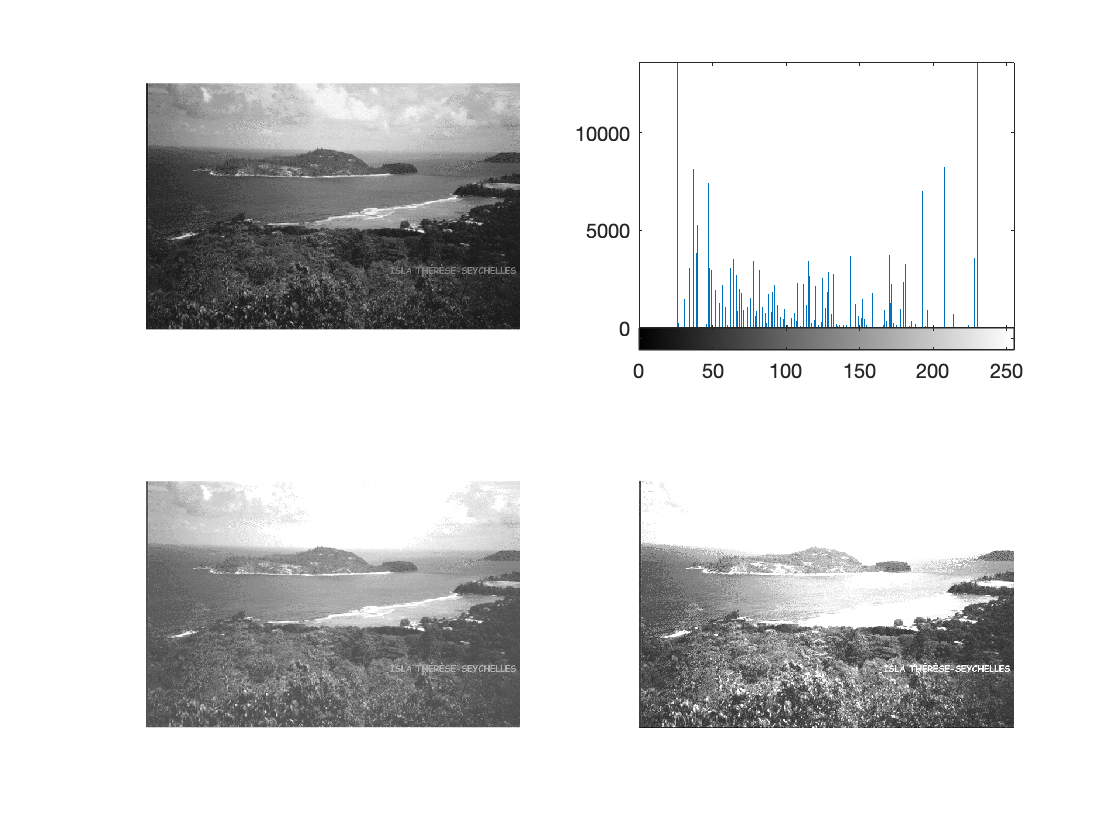

figure;
subplot(2,2,1)
imshow(i);
% values between 0.2 and 0.8 get mapped to 0.1 and 0.9 respectively
% result should be a picture with higher contrast
i_bright_1 = imadjust(i, [0.2 0.8], [0.1 0.9]); 

subplot(2,2,2);
imshow(i_bright_1);
i_bright_2 = i + 50;
subplot(2,2,3);
% just adding a constancompt to the picture. Result should be slightly brighter
% picture

imshow(i_bright_2);
% multiplying by a constant. Result should be different from i_bright_2.
% dark pixels should stay dark (e.g. 2*2 = 4) and gray and white pixels should get a
% lot brighter (e.g. 100*2=200)
i_bright_3 = i * 2;
subplot(2,2,4);
imshow(i_bright_3);

% 7.
fprintf('Exercise 7');

Exercise 7

figure;
% Using a simple filter by mapping all values below 127 to 0 (dark)
% and all values above 127 to 255 (white)
% result should be a high contrast picture with the loss of many details
dark_filter = i <= 127;
bright_filter = i > 127;
i_simple_logic = i;
i_simple_logic(dark_filter) = 0;
i_simple_logic(bright_filter) = 255;
subplot(1,2,1);
imshow(i_simple_logic);

% Using the mean value as threshhold
% result should also be high contrast but without that much loss as in the
% other picture
mean_i = uint8(mean(i, 'all'));
dark_filter = i <= mean_i;

dark_filter = 422×640 logical array
   1   1   1   1   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   0   1   1   1   1   1   1   0   0   0   0   0   0   1   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   0   1   1   0   1   0   1   0   1   0   0   0   0   0   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   0   1   0   1   0   1   0   1   0   0   0   1   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   0   0   0   0   1   0   1   0   1   0   1   0   0   1   0   0   1   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

bright_filter = i > mean_i;

bright_filter = 422×640 logical array
   0   0   0   0   1   0   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   1   0   0   0   0   0   0   1   1   1   1   1   1   0   0   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   1   0   0   1   0   1   0   1   0   1   1   1   1   1   1   0   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   1   0   1   0   1   0   1   0   1   1   1   0   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   1   1   1   1   0   1   0   1   0   1   0   1   1   0   1   1   0   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1  

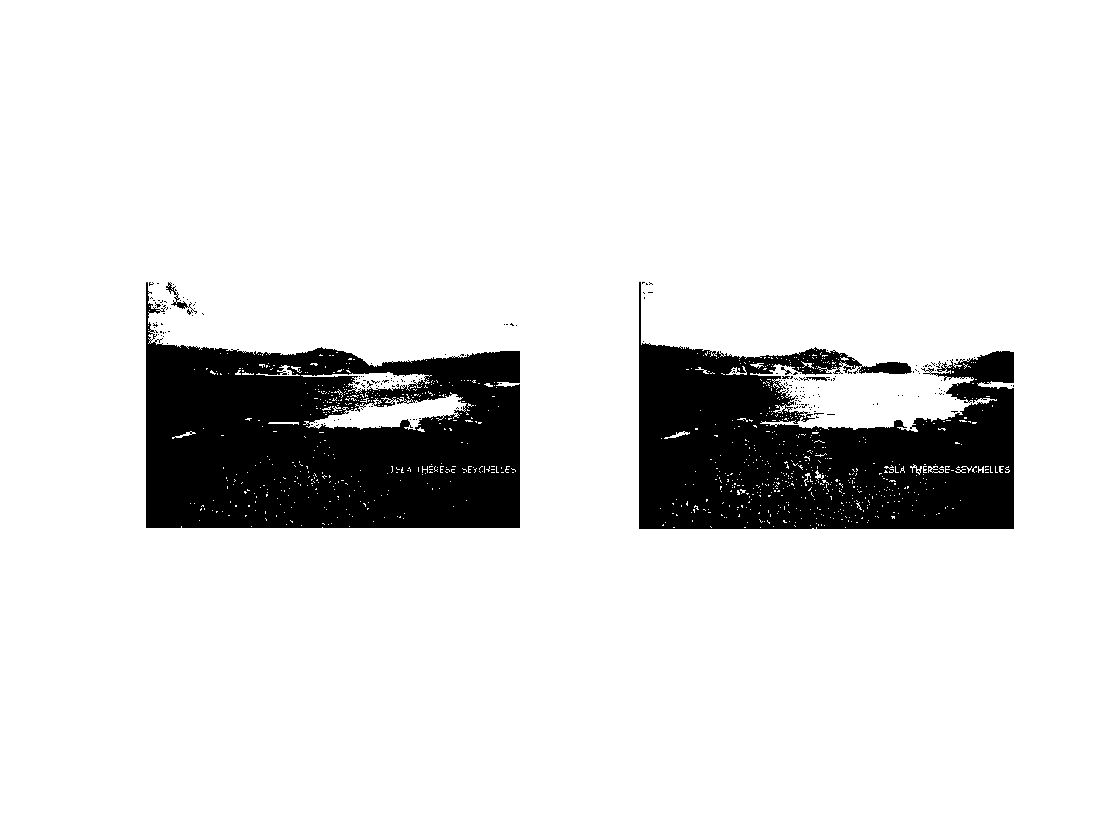

i_mean_logic = i;
i_mean_logic(dark_filter) = 0;
i_mean_logic(bright_filter) = 255;
subplot(1,2,2);
imshow(i_mean_logic);

fprintf('mean_i = %d', mean_i);

mean_i = 106

% 8.
fprintf('Exercise 8');

Exercise 8

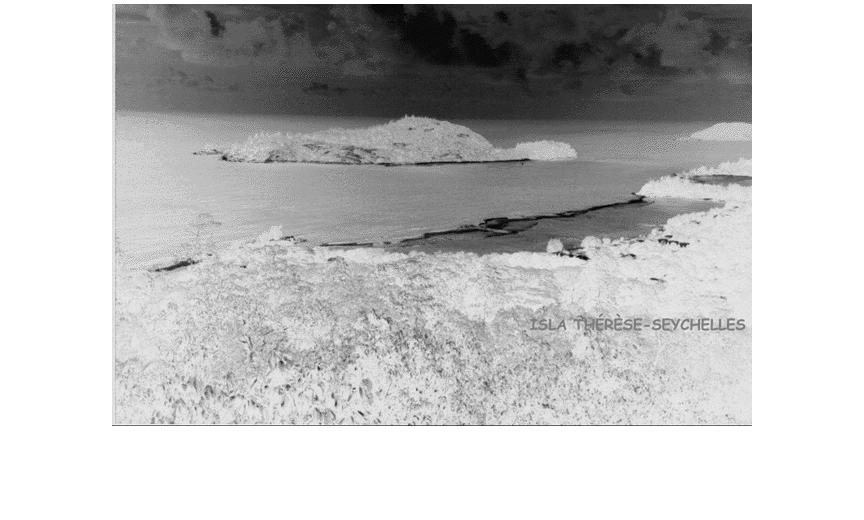

figure;
i_negative = 255 - i;
subplot(1,1,1);
imshow(i_negative);

% 9.
fprintf('Exercise 9');

Exercise 9

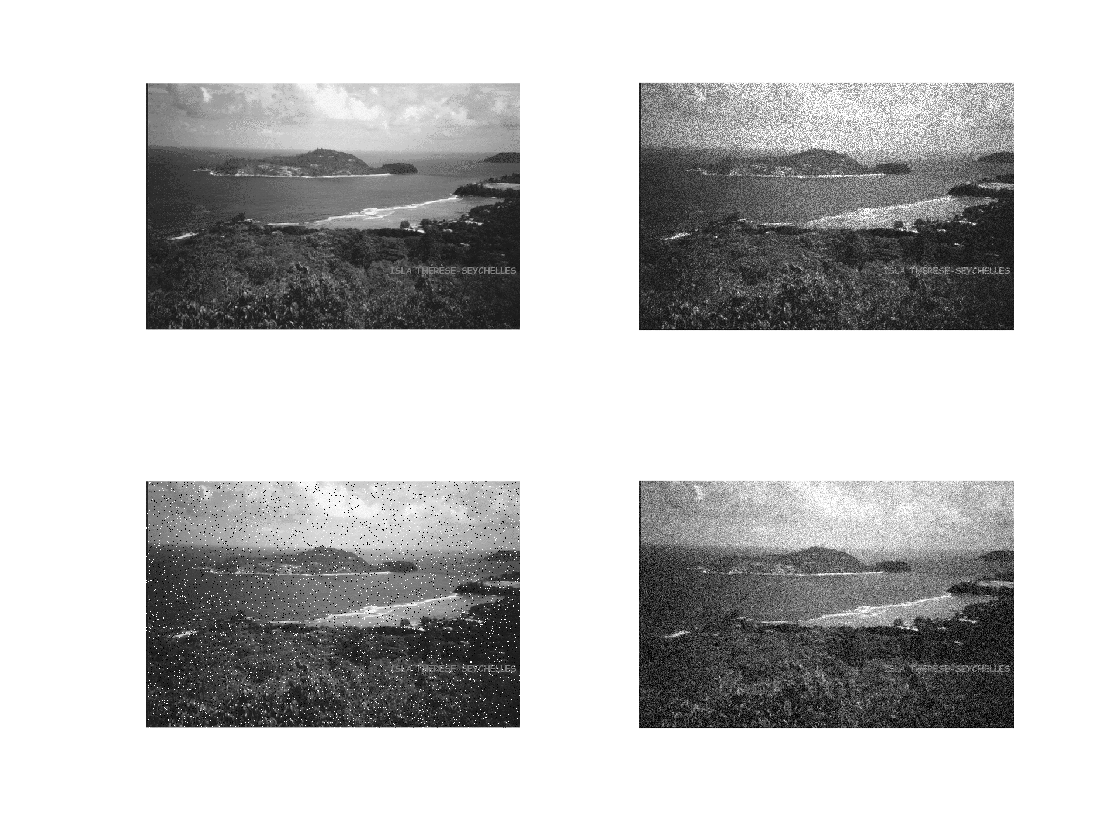

figure;
i_speckle = imnoise(i,'speckle');
i_salt_and_pepper = imnoise(i,'salt & pepper', 0.05);
i_gaussian = imnoise(i,'gaussian', 0, 0.01);
subplot(2,2,1);
imshow(i);
subplot(2,2,2);
imshow(i_speckle);
subplot(2,2,3);
imshow(i_salt_and_pepper);
subplot(2,2,4);
imshow(i_gaussian);

% 10.
fprintf('Exercise 10');

Exercise 10

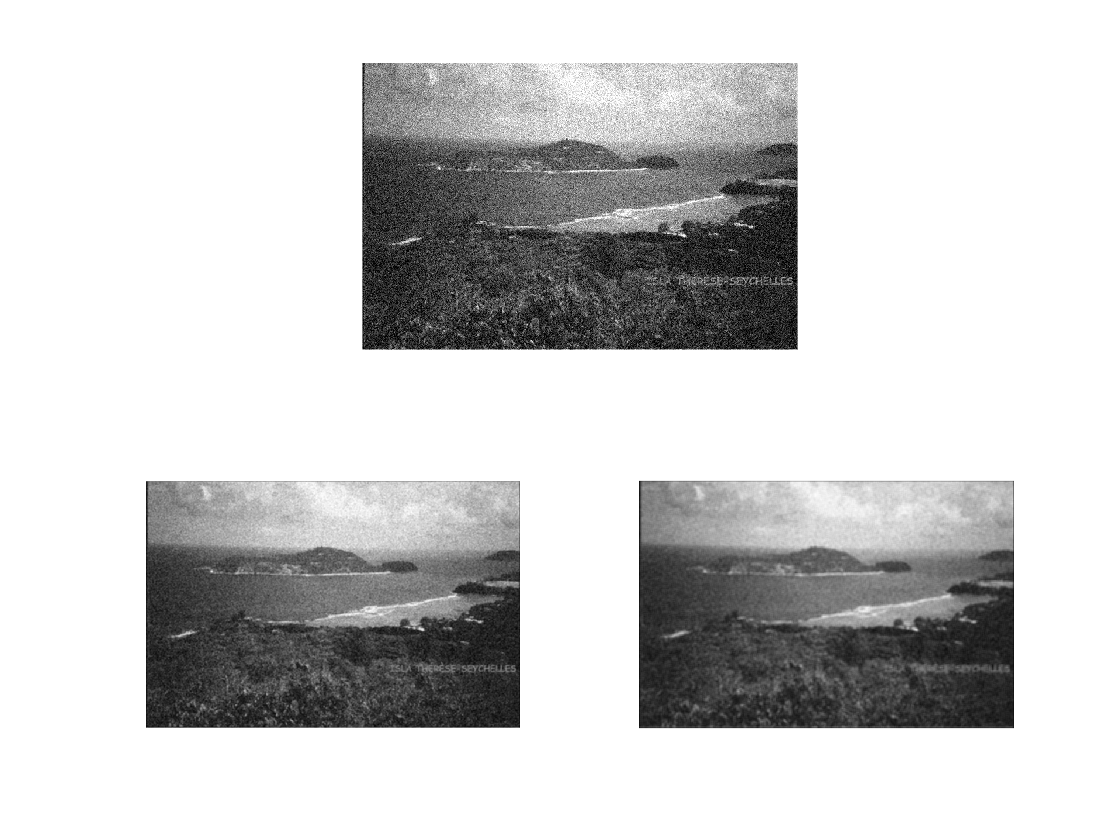

figure;
i_avg_3 = imfilter(i_gaussian,fspecial('average',[3 3]));
i_avg_5 = imfilter(i_gaussian,fspecial('average',[5 5]));
subplot(2,1,1);
imshow(i_gaussian);
subplot(2,2,3);
imshow(i_avg_3);
subplot(2,2,4);
imshow(i_avg_5);

% 11.
fprintf('Exercise 11');

Exercise 11

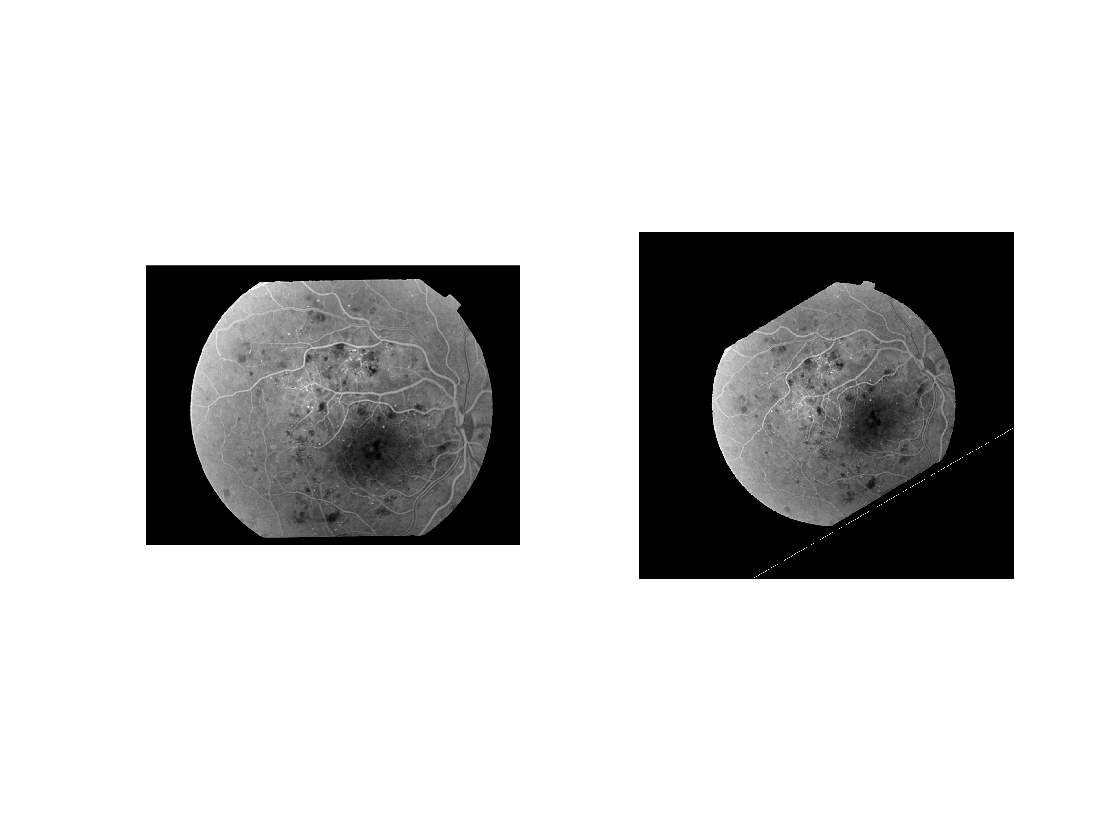

figure;
[I, cmap] = imread("venas.tif");
i_rotate = imrotate(I, 30);
subplot(1,2,1);
imshow(I);
subplot(1,2,2);
imshow(i_rotate);

% 12.
fprintf('Exercise 12');

Exercise 12

file_name = "output_pictures/noisy";
file_type = ".bmp";
for j = 1:16
    temp_file = imnoise(I,'gaussian', 0, 0.01);
    number = int2str(j);
    temp_name = strcat(file_name, number, file_type);
    imwrite(temp_file, temp_name);
end

% 13.
fprintf('Exercise 13');

Exercise 13

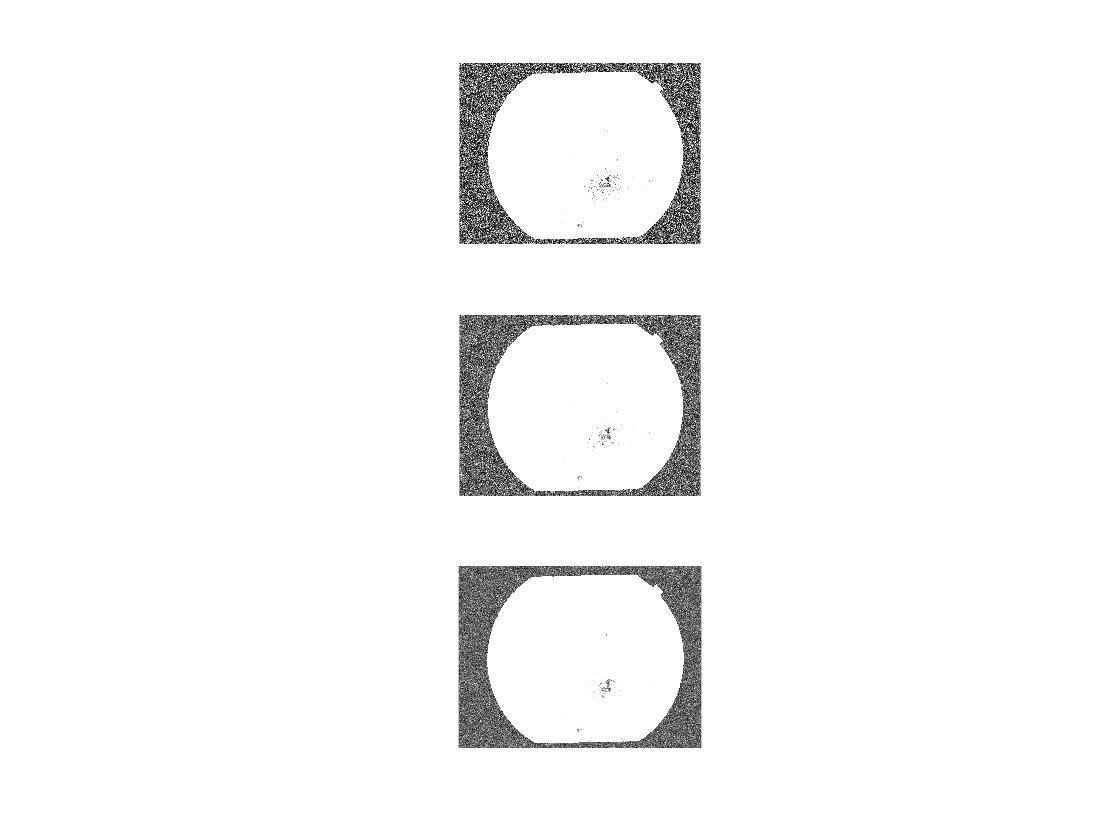

figure;
% create array with the same size as picture I
temp_avg = zeros(size(I), 'uint16'); 
for j = 1:4
    number = int2str(j);
    file_name = strcat("output_pictures/noisy", number, ".bmp");
    [temp, cmap] = imread(file_name);
    temp_avg = temp_avg + uint16(temp);
end
temp_avg = temp_avg/4;
subplot(3,1,1);
% when not converting the array back to uint8 it only shows black. Why?
% imhist(uint8(temp_avg));
imshow(uint8(temp_avg) * 10); % intensify noise
% imshow(uint8(temp_avg));
temp_avg = temp_avg * 0;
for j = 1:8
    number = int2str(j);
    file_name = strcat("output_pictures/noisy", number, ".bmp");
    [temp, cmap] = imread(file_name);
    temp_avg = temp_avg + uint16(temp);
end
temp_avg = temp_avg/8;
subplot(3,1,2);
% imhist(uint8(temp_avg));
imshow(uint8(temp_avg) * 10); % intensify noise
% imshow(uint8(temp_avg));
temp_avg = temp_avg * 0;
for j = 1:16
    number = int2str(j);
    file_name = strcat("output_pictures/noisy", number, ".bmp");
    [temp, cmap] = imread(file_name);
    
%     subplot(8,2,j);
%     imshow(temp);
%     file_name = strcat("output_pictures/filtered_noisy", number, ".bmp");
%     file_name = strcat(file_name);
%     imwrite(temp, file_name);
    
    temp_avg = temp_avg + uint16(temp);
end
temp_avg = temp_avg/16;
subplot(3,1,3);
% imhist(uint8(temp_avg));
imshow(uint8(temp_avg) * 10); % intensify noise

% imshow(uint8(temp_avg));